%addpath 'C:\Users\anonf\OneDrive\uni\phys project\matlab\iwave\development\matlab'
clear all

load_parameters

t_end = 0.01;
t = 0 : t_step : t_end;

%% generate axion frequency
f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);

%% generate signal and noise
signal = generate_axion_signal(t, f_sampling, f_axion, axion_power);
noise_power = calculate_noise_power(f_sampling, T)

noise_power = 1.5843e-17

noise = generate_thermal_noise(t, f_sampling, noise_power);

% atm we're running iwave on the signal not the signal + noise
iwave_input = noise;

band_width = 750;
f_0 = f_a

f_0 = 2.4178e+07

band = [f_0-band_width/2, f_0+band_width/2]

band = 	1.0e+07 *

    2.4178    2.4178


displayband = [f_0 - 20*axion_linewidth, f_0 + 20*axion_linewidth]

displayband = 	1.0e+07 *

    2.4168    2.4188



signal_power_broad = bandpower(signal)

signal_power_broad = 1.5000e-21

noise_power_broad = bandpower(noise)

noise_power_broad = 1.5833e-17

signal_power_in_band = bandpower(signal, f_sampling, band)

signal_power_in_band = 9.2777e-22

noise_power_in_band = bandpower(noise, f_sampling, band)

noise_power_in_band = 1.4272e-22

power_ratio_in_band = bandpower(signal, f_sampling, band) / bandpower(noise, f_sampling, band)

power_ratio_in_band = 6.5008

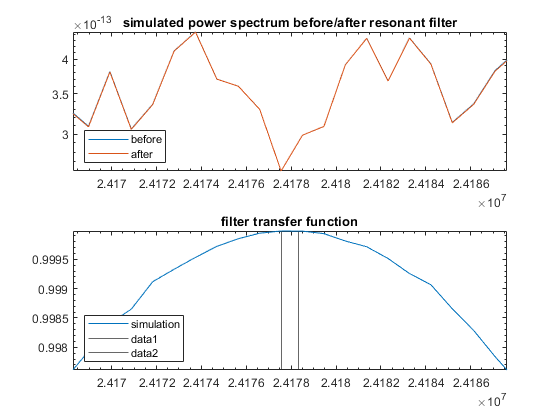

%band = [f_0-band_width*0.2, f_0+band_width*0.8];%input_power = bandpower(iwave_input  ,f_sampling,[f_0 - axion_linewidth/2, f_0 + axion_linewidth/2])
%input_power = bandpower(iwave_input_f,f_sampling,[f_0 - axion_linewidth/2, f_0 + axion_linewidth/2])

signal_f = bandpass(signal, band, f_sampling, 'Steepness',0.9999);
noise_f = bandpass(noise, band, f_sampling, 'Steepness',0.9999);

display_spectra(noise, noise_f, f_sampling, displayband);
xline(band)


SNR_band = bandpower(signal_f)/bandpower(noise_f)

SNR_band = 0.0614

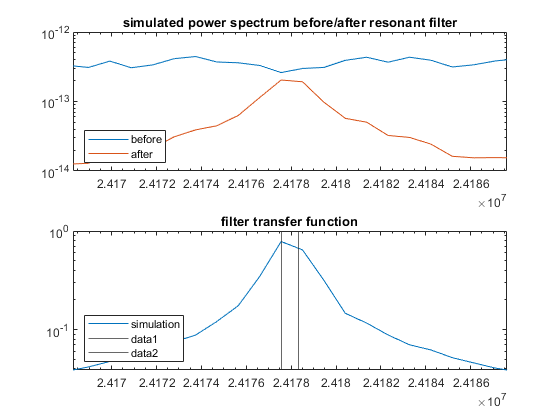

wo = f_0 / (f_sampling/2);  
bw = band_width / (f_sampling/2);
[b, a] = iirpeak(wo, bw);
signal_f = filter(b, a, signal);
noise_f = filter(b, a, noise);

display_spectra(noise, noise_f, f_sampling, displayband);
xline(band)


SNR_band = bandpower(signal_f)/bandpower(noise_f)

SNR_band = 6.6284

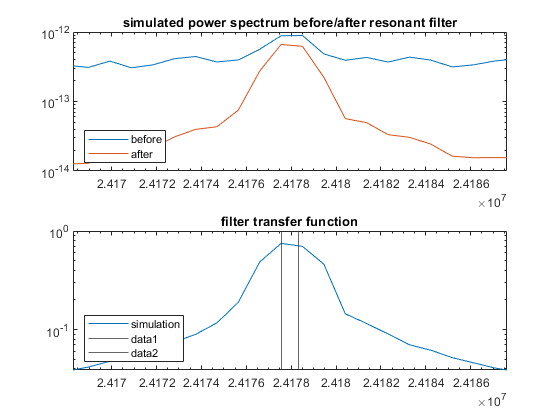

% now we've decided the best filtering, do it
wo = f_0 / (f_sampling/2);  
bw = band_width / (f_sampling/2);
[b, a] = iirpeak(wo, bw);
iwave_input_f = filter(b, a, signal + noise);
%iwave_input_f = prepare_iwave_input(signal + noise, f_0, band_width, f_sampling)
display_spectra(signal + noise, iwave_input_f, f_sampling, displayband);
xline(band)

power_in_band = bandpower(iwave_input_f, f_sampling, band)

power_in_band = 4.8590e-22

power =         bandpower(iwave_input_f, f_sampling, [0, f_sampling/2.001])

power = 7.1248e-22

fraction_of_power_in_band_after = power_in_band / power

fraction_of_power_in_band_after = 0.6820

%% run iwave
tau_iwave = 1e-5; % before adding noise
tau_iwave = 3e-4;
tau_iwave = 4e-4; % for 1* mult
%tau_iwave = 1e-4
%tau_iwave = 30e-4
%tau_iwave = 15e-4
%tau_iwave = 3.8e-4/0.1;
%tau_iwave = 20e-4; % for 10* mult

% front to chop off
% start_secs = 4 * tau_iwave;
start_secs = t(end)/4;
assert(start_secs < t(end)/3)
start = round(start_secs * f_sampling);

[f_iwave, amp] = run_iwave(iwave_input_f, f_sampling, f_0, tau_iwave);

% don't need to plot every single point
div = 1000;

slice = (1:div:length(t));
t_small       = t(slice);
f_axion_small = f_axion(slice);
f_iwave_small = f_iwave(slice);
amp_small = amp(slice);

start = round(start / div)

start = 625

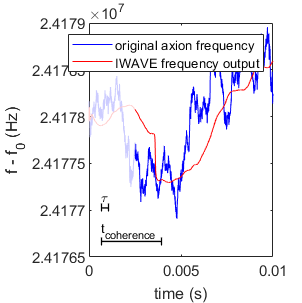

% plot iwave before and after
figure
adstyle(8, 8);

plot(t_small(start:end), f_axion_small(start:end)-0, 'Color', [0,0,1], 'DisplayName','original axion frequency')
y_lim = ylim();
hold on
plot(t_small(1:start),   f_axion_small(1:start)  -0, 'Color', [0.8,0.8,1], 'HandleVisibility','off')
plot(t_small(start:end), f_iwave_small(start:end)-0, 'Color', [1,0,0], 'DisplayName','IWAVE frequency output')
plot(t_small(1:start),   f_iwave_small(1:start)  -0, 'Color', [1,0.8,0.8], 'HandleVisibility','off')
ylim(y_lim)
x_lim = xlim();
legend()
xlabel('time (s)')
ylabel('f - f_0 (Hz)')

y_width = y_lim(2) - y_lim(1);
x_width = x_lim(2) - x_lim(1);

x_start = x_lim(1) + x_width/15;
y_1 = y_lim(1) + y_width/15;
y_2 = y_1 + y_width/7;

plot([x_start, x_start + t_coherence], [y_1, y_1], '-|', 'Color','black', 'LineWidth',1, 'HandleVisibility','off')
plot([x_start, x_start + tau_iwave], [y_2, y_2], '-|', 'Color','black', 'LineWidth',1, 'HandleVisibility','off')

text(x_start, y_1 + y_width/20, 't_{coherence}')
text(x_start, y_2 + y_width/20, '\tau')

%saveas(gca, 'figures/chop.eps', 'epsc');

% now remove the start as it can go a bit off
% start_samples = start_secs * f_sampling;
% t       = t      (start_samples:end);
% f_iwave = f_iwave(start_samples:end);
% f_axion = f_axion(start_samples:end);
% signal  = signal (start_samples:end);
% noise   = noise  (start_samples:end);

% find avg diff between iwave and original
% avg_dist_dynamic = rms(f_iwave - f_axion);
% Qmax_dynamic = 2 * f_0 / avg_dist_dynamic;
% 
% avg_dist_static = rms(f_0 * ones(size(t)) - f_axion);
% Qmax_static = 2 * f_0 / avg_dist_static;